% AE6511 Hw3 Problem 2 MATLAB code
% Tomoki Koike
clear all; close all; clc;  % housekeeping commands

syms psi_1 psi_2 theta
assume(0 <= psi_1 & psi_1 < 2*pi);
assume(0 <= psi_2 & psi_2 < 2*pi);
assume(0 <= theta & theta < 2*pi);
a = 10;
b = 2;
m = b/a;

alpha = -pi;
beta = 1;
g = 32;

% 10th order Taylor series of sine and cosine to make equation solvable
tsin = @(x) taylor(sin(x), 'Order', 25);
tcos = @(x) taylor(cos(x), 'Order', 25);
eqn0 = 1 - tcos(theta) - m * (theta - tsin(theta)) == 0;

% Brachistrochrone solution 
sol = double(solve([eqn0], [theta]))

sol =          0
         0
    4.5946


theta_sol = sol(sol > 0)

theta_sol = 4.5946

tf_brachi = sqrt(beta/g) * theta_sol

tf_brachi = 0.8122


% Ramp solution 
tf_ramp = sqrt(2 * (a^2 + b^2)/ g / b)

tf_ramp = 1.8028


% Delta T
DT = tf_ramp - tf_brachi

DT = 0.9906

% Get the exact cycloid
syms A
x_cyc = @(x) A*(x - sin(x));
y_cyc = @(x) A*(1 - cos(x));

A1 = vpasolve(subs(x_cyc(theta), theta, theta_sol)==a, A)

$$A1 = 1.7897$$

A2 = vpasolve(subs(y_cyc(theta), theta, theta_sol)==b, A)

$$A2 = 1.7897$$

assert(round(A1 - A2, 3) == 0, 'Precision is not acceptable for A not matching.')
A_sol = A1;

% Get the location of point on ramp 
syms X
x_ramp_term = solve(sqrt(2*X*(1 + m^2)/g/m) == tf_brachi, X)

$$x\_ramp\_term = 2.0298$$

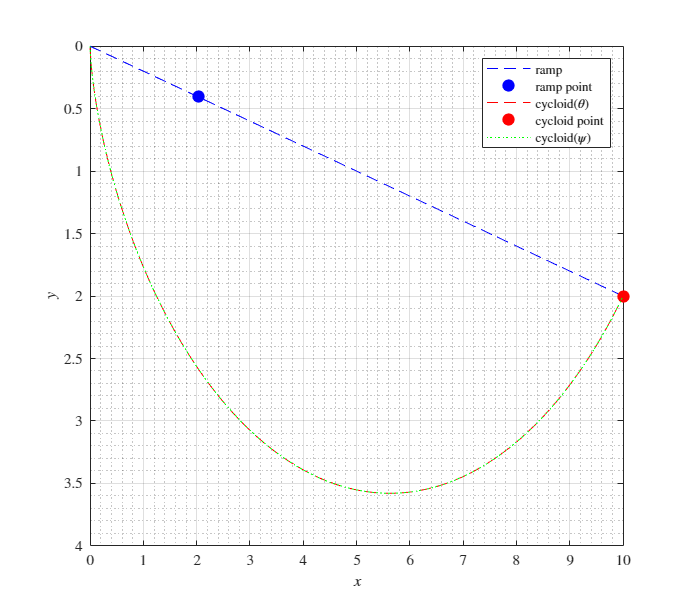

% Plot

% Cycloid
th = linspace(0, theta_sol, 100);
xc = A_sol * (th - sin(th));
yc = A_sol * (1 - cos(th));

% second cycloid for verification
psi = linspace(pi, pi + theta_sol, 100);
% beta = A_sol and alpha = - pi*A_sol
xc2 = -pi*A_sol + A_sol*(psi + sin(psi));
yc2 = A_sol * (1 + cos(psi));


% Ramp
x_ramp = linspace(0, a, 100);
y_ramp = x_ramp * m;

set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
fig = figure("Renderer","painters","Position",[60 60 900 800]);
    plot(x_ramp, y_ramp, '--b', 'DisplayName', 'ramp')
    hold on; grid on; grid minor; box on;
    plot(x_ramp_term, x_ramp_term*m, '.b', 'MarkerSize',25, 'DisplayName','ramp point')
    plot(xc, yc, '--r', 'DisplayName', 'cycloid($\theta$)')
    plot(xc(end), yc(end), '.r', 'MarkerSize',25, 'DisplayName','cycloid point')
    plot(xc2, yc2, ':g', 'DisplayName', 'cycloid($\psi$)')
    hold off
    xlabel('$x$')
    ylabel('$y$')
    legend
    set(gca, 'Ydir','reverse');
saveas(fig, 'p2_brachi_2.png')